# $L_0$ L0 norm

Number of non zero components in $\mathbf{x}$

n = 10;
x = rand(n,1);
x(x<0.5) = 0;
lo_x = sum(x~=0)

lo_x = 4

(not strictly a norm function)

**Understanding the **$L_0$** Norm: Counting the Non-Zero**

The $L_0$ norm of a vector, denoted as $\|x\|_0$  is defined as the number of non-zero elements in that vector. 

For instance, for the vector $\mathbf{x}=\left[\matrix{ 0\cr 5\cr 0\cr -2\cr 3} \right]$ , the $L_0$ norm $\|x\|_0$ is $3$, as there are three non-zero elements $5, -2$ and $3$.

**Mathematical Definition:**

For a vector $\mathbf{x} \in R^n$, the $L_0$ norm is given by:


$$\|x\|_0=\sum_{i=1}^n|x_i|^0$$


where $|x_i|^0 = 1$ if $x_i \neq 0$ and $0$ if $x_i=0$.

# $L_1$ L1 norm

Sum of absolute value of the components of $\mathbf{x}$

n = 5;
x = randi([-1,4],n,1)

x =      2
    -1
     1
    -1
     4


l1_x = sum(abs(x))

l1_x = 9

is the sum of the absolute values of each elements of $\mathbf{x}$. 


$$\|\mathbf{x}\|_1=\sum_{i=1}^n|x_i|$$


Visualizing $|x|$

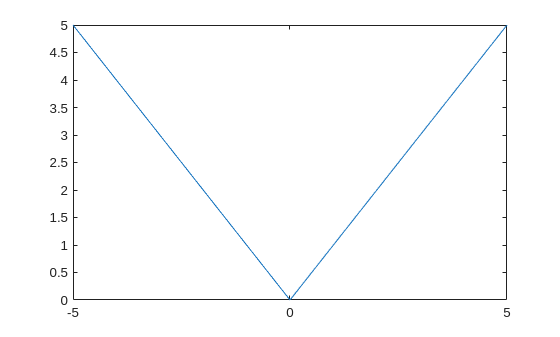

x1 = single(-5:0.2:5);
y = abs(x1);
plot(x1,y)

clearvars

Visualizing $|\mathbf{x}| , \mathbf{x} \in R^2$

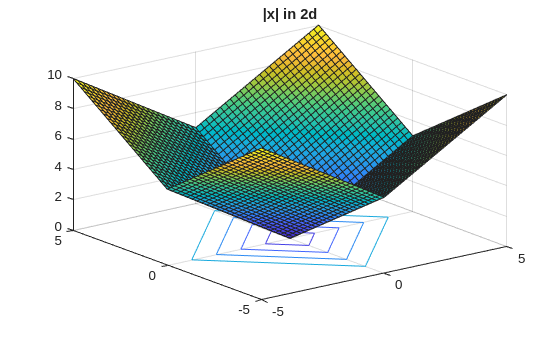

x1 = single(-5:0.2:5);
x2 = x1;
[X1,X2] = meshgrid(x1,x2);
Z1 = abs(X1)+abs(X2);
surf(X1,X2,Z1);hold on
contour(X1,X2,Z1,1:4); hold off
title("|x| in 2d")

$L_1$** Unit norm ball in 2 dimension**


$$\mathbf{x} \in R^2$$


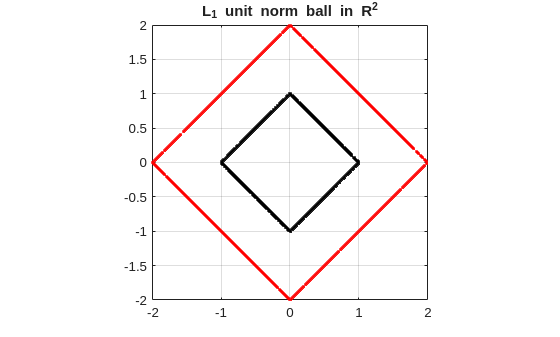

clearvars
x = rand(2,2500)-0.5;
x = x./sum(abs(x));
x2 = 2*x;
plot(x(1,:),x(2,:),'k.');hold on
plot(x2(1,:),x2(2,:),'r.');hold off
axis equal
title("L_1 unit norm ball in R^2")
grid on
xlim([-2 2])
ylim([-2 2])

$L_1$**Unit norm ball in 3 dimension**


$$\mathbf{x} \in R^3$$


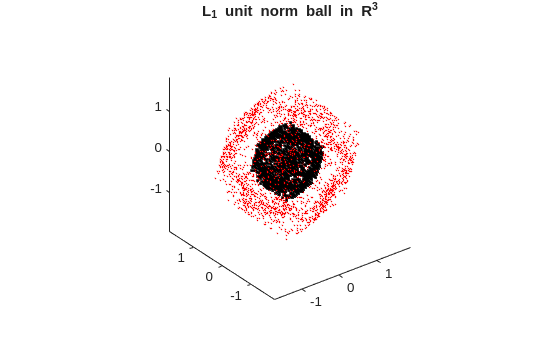

clearvars
x = rand(3,2500)-0.5;
x = x./sum(abs(x));
plot3(x(1,:),x(2,:),x(3,:),'k.');hold on
axis equal
title("L_1 unit norm ball in R^3")

x2 = 2*x;
plot3(x2(1,:),x2(2,:),x2(3,:),'r.',MarkerSize=0.5);
hold off

# Weighted $L_1$L1 norm

n = 5;
x = randi([-1,4],n,1)

x =      0
    -1
     3
     1
     2


w = rand(n,1);
w = w/sum(w)

w =     0.3359
    0.0987
    0.2185
    0.2706
    0.0763


wl1_x = w'*abs(x)

wl1_x = 1.1774

# $L_2$ L2 norm

Sqrt of sum of squares of the components of $\mathbf{x}$

n = 5;
x = randi([-1,4],n,1)

x =      3
    -1
     1
     0
     3



l2_x = sqrt(sum(x.*x))

l2_x = 4.4721

l2_x = sqrt(sum(x.^2))

l2_x = 4.4721

l2_x = sqrt(dot(x,x))

l2_x = 4.4721

is the square root of the sum of the squares of each values of $\mathbf{x}$. 

$\|\mathbf{x}\|_2^2=\sum_{i=1}^nx_i^2$ square of the $L_2$ norm

$L_2$ norm $= \sqrt{\sum_{i=1}^nx_i^2}$

Visualizing $|\mathbf{x}|_2 , \mathbf{x} \in R^2$

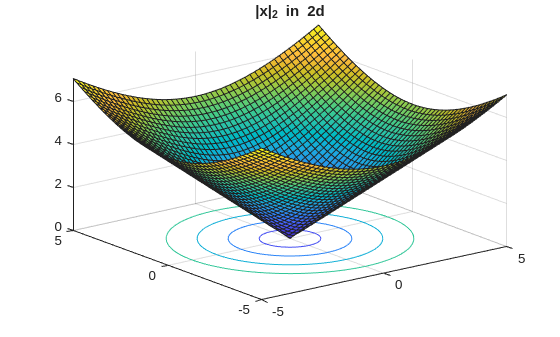

x1 = single(-5:0.2:5);
x2 = x1;
[X1,X2] = meshgrid(x1,x2);
Z1 = sqrt(X1.^2 + X2.^2);
surf(X1,X2,Z1);hold on
contour(X1,X2,Z1,1:4); hold off
title("|x|_2 in 2d")

$L_2$** Unit norm ball in 2 dimension**

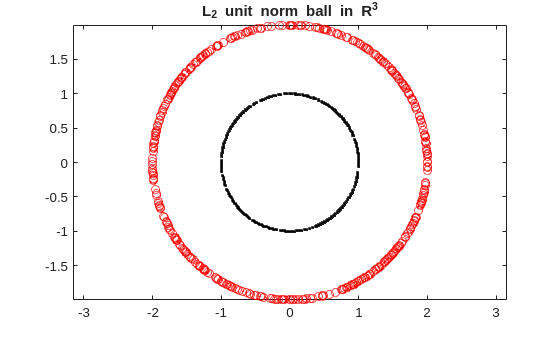

x = rand(2,500)-0.5;
x = x./(sqrt(sum(x.^2)));

plot(x(1,:),x(2,:),'k.');hold on
axis equal
title("L_2 unit norm ball in R^3")
x = 2*x./(sqrt(sum(x.^2)));
plot(x(1,:),x(2,:),'ro');hold off

$L_2$** Unit norm ball in 3 dimension**

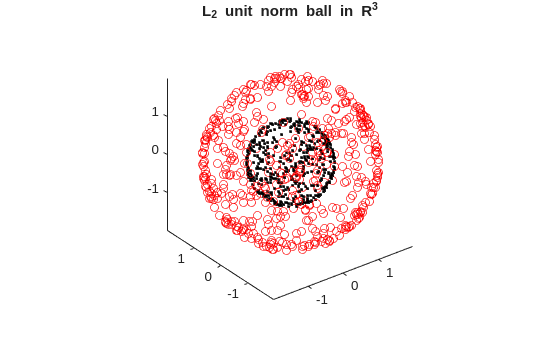

x = rand(3,500)-0.5;
x = x./(sqrt(sum(x.^2)));

plot3(x(1,:),x(2,:),x(3,:),'k.');hold on
axis equal
title("L_2 unit norm ball in R^3")
x = 2*x./(sqrt(sum(x.^2)));
plot3(x(1,:),x(2,:),x(3,:),'ro');hold off

# $L_\infty$ norm

is the maximum of the absolute values of $\mathbf{x}$. 


$$\|\mathbf{x}\|_\infty=\max \{|x_i|\}$$



$$\mathbf{x} \in R^2$$


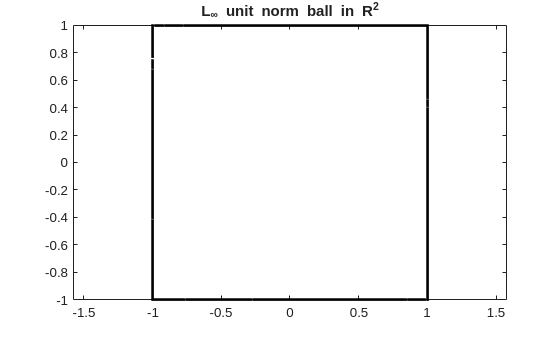

x = rand(2,2500)-0.5;
x = x./(max(abs(x)));
plot(x(1,:),x(2,:),'k.')
axis equal
title("L_\infty unit norm ball in R^2")


$$\mathbf{x} \in R^3$$


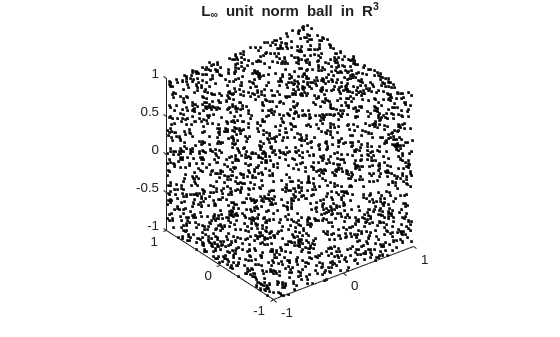

x = rand(3,2500)-0.5;
x = x./(max(abs(x)));
plot3(x(1,:),x(2,:),x(3,:),'k.')
axis equal
title("L_\infty unit norm ball in R^3")

# $L_p$ norm

is defined as  


$$\|\mathbf{x}\|_p = \left(\sum_{i=1}^n |x_i|^p\right)^{\frac{1}{p}}$$


with $1\leq p \lt \infty$


$$\mathbf{x} \in R^2$$


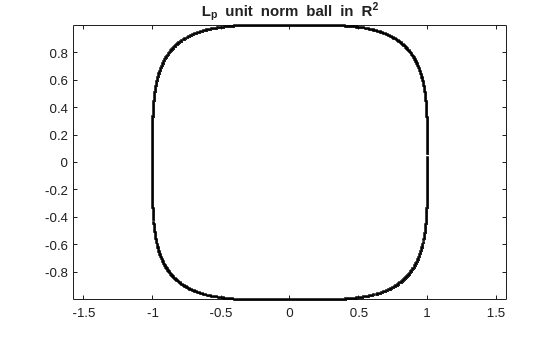

x = rand(2,2500)-0.5;
p = 4;
x = x./power(sum(abs(x).^p),1/p);
plot(x(1,:),x(2,:),'k.')
axis equal
title("L_p unit norm ball in R^2")


$$\mathbf{x} \in R^3$$


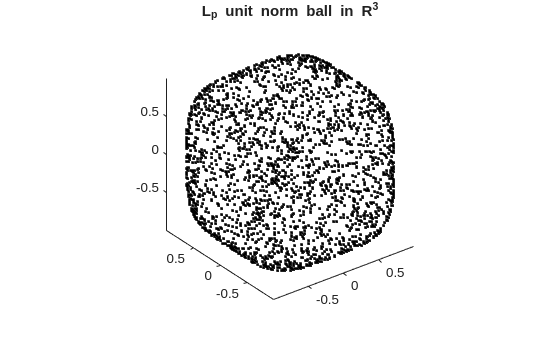

x = rand(3,2500)-0.5;
p = 4;
x = x./power(sum(abs(x).^p),1/p);
plot3(x(1,:),x(2,:),x(3,:),'k.')
axis equal
title("L_p unit norm ball in R^3")

# $L_*$ Trace norm, Schatten 1-norm, Nuclear norm

$\ell_1$ norm of the vector of singular values of a matrix $A$

sum of singular values

rng(100)
X = randi([-1,4],3,4);

Ln_X = sum(svd(x))

Ln_X = 102.7801

# Frobenius norm

$\ell_2$ norm of the vector of singular values of a matrix $A$

rng(100)

A = randi([-1,3],3,5)

A =      1     3     2     1    -1
     0    -1     3     3    -1
     1    -1    -1     0     0



norm(A,"fro")

ans = 6.2450


sqrt(sum(A.^2,"all"))

ans = 6.2450

sqrt(dot(A(:),A(:)))

ans = 6.2450

sqrt(sum(svd(A).^2))

ans = 6.2450

sqrt(trace(A'*A))

ans = 6.2450

sqrt(trace(A*A'))

ans = 6.2450

# $L_{2,1}$ L21norm

Sum of the $L_2$ norm of the column vectors of $A$

rng(100)

A = randi([-1,3],3,5)

A =      1     3     2     1    -1
     0    -1     3     3    -1
     1    -1    -1     0     0



sum(sqrt(sum(A.^2)))

ans = 13.0490

# Matrix inner product

The inner product of $2\space m \times n$ matrices $A$ and $B$ is defined as 

trace($A^TB$). It is equal to the dot product of the vectorized form of $A$ and $B$.

rng(100)

A = randi([-1,3],4,2)

A =      1    -1
     0    -1
     1     2
     3     3


B = randi([-1,3],4,2)

B =     -1    -1
     1    -1
     3     0
     0     3



trace(A'*B)

ans = 13

trace(B'*A)

ans = 13

trace(A*B')

ans = 13

trace(B*A')

ans = 13


dot(A(:),B(:))

ans = 13

# Operator Norm

Maximum value of the singular value of a matrix $A$

# Weighted $L_{2,1}$ norm

A = repmat(1:5,3,1)

A =      1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5


w = rand(5,1)

w =     0.8117
    0.1719
    0.8162
    0.2741
    0.4317


L21 = sum(sqrt(sum(A.^2)))

L21 = 25.9808

x2 = sqrt(sum(A.^2))'

x2 =     1.7321
    3.4641
    5.1962
    6.9282
    8.6603


WL21 = w'*x2

WL21 = 11.8802

sum(w.*x2)

ans = 11.8802

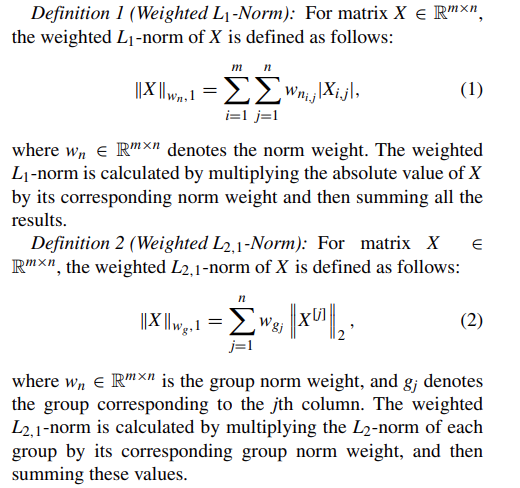

Team C14

cd("/media/user/DATA4LINUX/new1/Repos/Mine/MFC4_22MAT230/")
mlxfile = matlab.desktop.editor.getActive().Filename;
outfile = mlxfile + ".pdf";
export(matlab.desktop.editor.getActive().Filename, outfile);